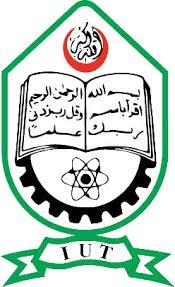

## **Islamic University of Technology  **

## **Name                        :** Shazzad Ahmed

## **Student ID                : **220021108 

## **Section                     : **A- 2

## **Department              :** Electrical & Electronic Engineering  

## **Course No                :** EEE 4408 

## **Course Name           :** Random Signals & Processes Lab  

## **Experiment No         : **03

## **Date of Submission : 03**.08.2025

#### Problem-1: Calculate the Probability for a Gaussian Random Variable

For a Gaussian random variable X with mean 10 and standard deviation 2, find the probability that X is less than 12.

`MATLAB Code & Explanation:`

mu=10;                % Mean of the distribution
sigma=2;              % Standard deviation
x=12;                 % Value to find probability for
% Calculate cumulative distribution function at x=12
p=normcdf(x,mu,sigma); 
disp(['P(X<12)= ',num2str(p)]);

P(X<12)= 0.84134


#### Problem-2: Signal-to-Noise Ratio (SNR)

Generate a sinusoidal signal with an average power of 2 W. Then, create a white Gaussian noise sequence with an average power of 0.2 W. Combine the signal and noise and plot the resulting signal. The desired Signal-to-Noise Ratio (SNR) is 10.

`MATLAB Code & Explanation:`

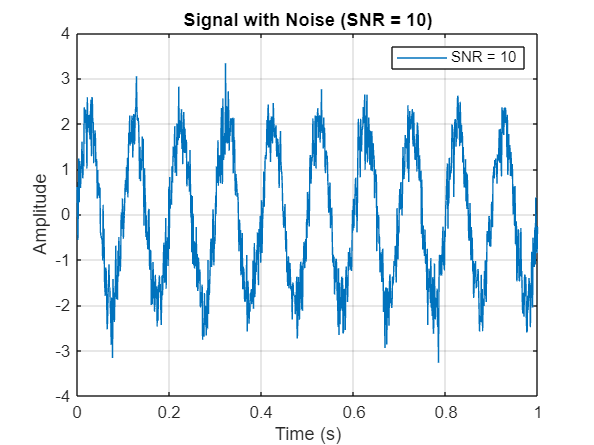

t=(0:1023)/1024; % Creates a time vector from 0 to 1 with 1024 points
signal_power=2; % Desired average power of the signal is 2 W
signal=sqrt(2*signal_power)*sin(2*pi*10*t); % Creates a sine wave with the specified power
noise_power=0.2; % Desired average power of the noise is 0.2 W
% randn generates Gaussian noise with zero mean and variance of 1. [cite: 41]
% To get the desired power P, I multiply by sqrt(P). [cite: 43]
noise=sqrt(noise_power)*randn(1,length(t)); % Generates white Gaussian noise
snr_signal=signal+noise; % Adds the signal and noise sequences
plot(t,snr_signal); % Plots the combined signal against time
title('Signal with Noise (SNR = 10)'); % Adds a title to the plot
xlabel('Time (s)'); % Labels the x-axis
ylabel('Amplitude'); % Labels the y-axis
legend('SNR = 10'); % Adds a legend to identify the plot
grid on; % Displays a grid on the plot

#### Problem-3: Cumulative Sum Example

Given a probability vector p = [0.1 0.3 0.6], find the cumulative sum.

`MATLAB Code & Explanation:`

p=[0.1 0.3 0.6];   
y=cumsum(p);        % Computes the cumulative sum
disp('Cumulative sum:');

Cumulative sum:


disp(y);

    0.1000    0.4000    1.0000



#### Problem-4: Generate and Analyze Random Signals

Create two random signals, shift one, compute their cross-correlation, and find the time lag with maximum similarity.

`MATLAB Code & Explanation:`

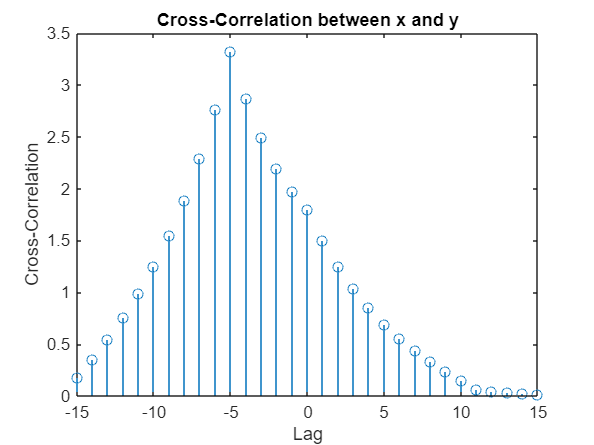

n=0:15;
x=0.84.^n;                    % First signal, decaying exponential
y=circshift(x,5);             % Second signal, shifted by 5 points
[c,lags]=xcorr(x,y);         % Cross-correlation
stem(lags, c);
xlabel('Lag');
ylabel('Cross-Correlation');
title('Cross-Correlation between x and y');

[max_val,idx]=max(c);         
disp(['Maximum at lag: ',num2str(lags(idx))]);

Maximum at lag: -5


#### Problem-5: Fit a Normal Distribution and Plot PDF/CDF

Fit a normal distribution to sample data and plot both its PDF and CDF.

`MATLAB Code & Explanation:`

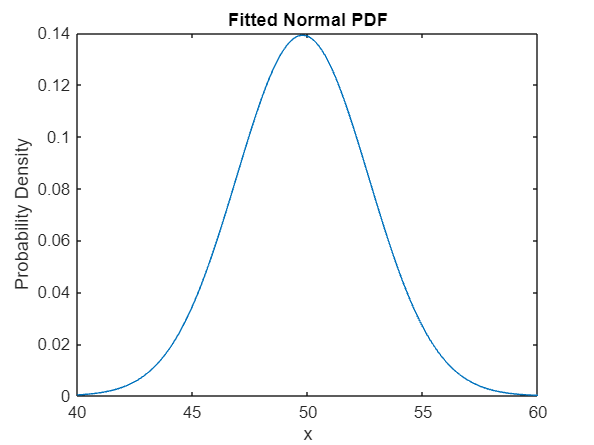

data=randn(1,100)*3+50;   % 100 samples from N(50, 9)
pd=fitdist(data','Normal');   % Fit normal distribution
% Plot PDF
x=40:0.1:60;
y_pdf=pdf(pd,x);
figure;
plot(x,y_pdf);
title('Fitted Normal PDF');
xlabel('x');
ylabel('Probability Density');

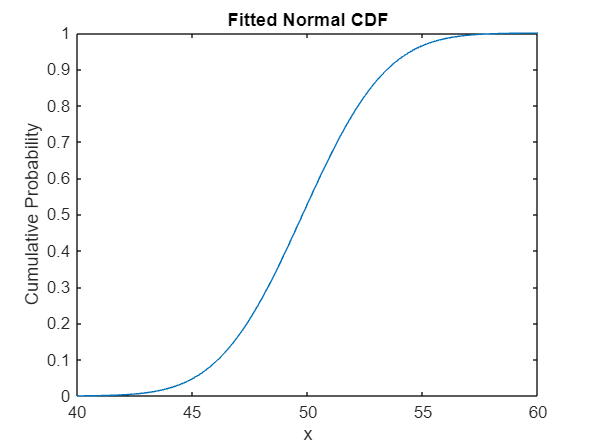

% Plot CDF
y_cdf=cdf(pd,x);
figure;
plot(x,y_cdf);
title('Fitted Normal CDF');
xlabel('x');
ylabel('Cumulative Probability');